# Work with Specialized ROS Messages

This example shows how to handle message types for laser scans, uncompressed and compressed images, point clouds, camera info, occcupancy grid, and octomap messages.

These are some commonly used ROS messages stored data in a format, that requires some transformation before it can be used for further processing. MATLAB® can help you by formatting these specialized ROS messages for easy use.

Prerequisites: [Work with Basic ROS Messages](docid:ros_ug.mw_2b4c1056-431d-4413-a812-7cd07f4d9a36)

## Load Sample Messages

Loaded messages are populated with real and synthetic data from various robot sensors.

Produces the following variables:

- img - regular image

- imgcomp - compressed image

- ptcloud - point cloud

- quatmsg - quaternion

- mapMsg - map

- octomap - octomaps are voxelized/discretized 3D spaces

- scan - lidar scan

- tf - contains transformations across ros coordinate frames

load("specialROSMessageData.mat")

## Image Messages

MATLAB provides support for image messages, which always have the message type [`sensor_msgs/Image`](https://docs.ros.org/en/noetic/api/sensor_msgs/html/msg/Image.html).

Create an empty image message using [`rosmessage`](docid:ros_ref.bupf5_j_2) to see the standard ROS format for an image message. 

emptyimg = rosmessage("sensor_msgs/Image",DataFormat="struct")

emptyimg = struct with fields:
    MessageType: 'sensor_msgs/Image'
         Header: [1×1 struct]
         Height: 0
          Width: 0
       Encoding: ''
    IsBigendian: 0
           Step: 0
           Data: [0×1 uint8]


For convenience, an image message that is fully populated and is stored in the `img` variable is loaded from `specialROSMessageData.mat`.

Inspect the image message variable `img` in your workspace. The size of the image is stored in the `Width` and `Height` properties. ROS sends the actual image data using a vector in the `Data` property.

img

img = struct with fields:
    MessageType: 'sensor_msgs/Image'
         Header: [1×1 struct]
         Height: 480
          Width: 640
       Encoding: 'rgb8'
    IsBigendian: 0
           Step: 1920
           Data: [921600×1 uint8]


The `Data` property stores raw image data that cannot be used directly for processing and visualization in MATLAB. You can use the [rosReadImage](docid:ros_ref#buqbtm0) function to retrieve the image in a format that is compatible with MATLAB.

imageFormatted = rosReadImage(img);

The original image has a rgb8 encoding. By default, [rosReadImage](docid:ros_ref#buqbtm0) returns the image in a standard 480-by-640-by-3 `uint8` format. View this image using the [`imshow`](docid:matlab_ref.bvmnrxi-1) function.

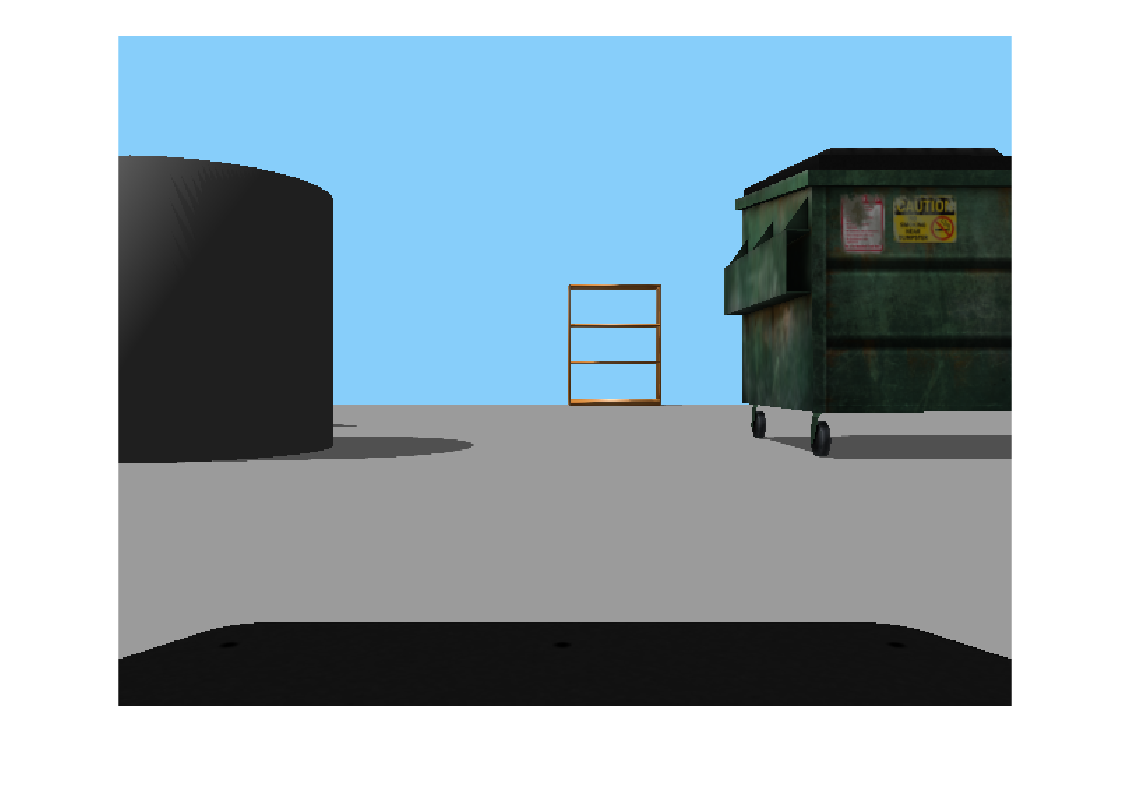

imshow(imageFormatted)

MATLAB® supports all ROS image encoding formats, and [rosReadImage](docid:ros_ref#buqbtm0) handles the complexity of converting the image data. In addition to color images, MATLAB also supports monochromatic and depth images.

Additionally, MATLAB provides the [rosWriteImage](docid:ros_ref#buqby1r-1) function to convert a MATLAB image to a ROS message using the function. Apply rudimentary object detection on the sample image with color thresholding. Visualize the modified image.  

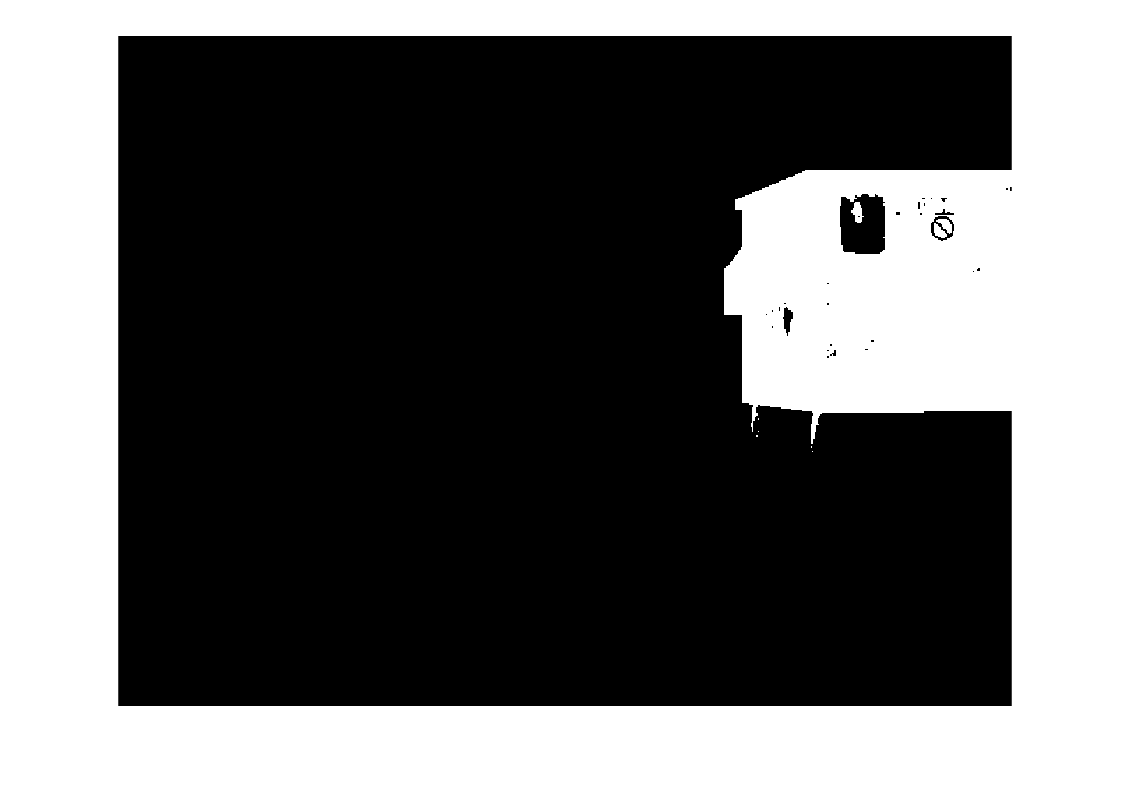

greenPercentage = 100*double(imageFormatted(:,:,2))./sum(imageFormatted,3);
thresholdImg = 255*uint8(greenPercentage > 35);
imshow(thresholdImg)

Write the modified image to a ROS message with the [rosWriteImage](docid:ros_ref#buqby1r-1) function. Since the modified image only has 1 channel and is of type `uint8`, use the `mono8` encoding.    

imageMsg = rosWriteImage(emptyimg,thresholdImg,Encoding="mono8");

## Compressed Image Messages

Many ROS systems send their image data in a compressed format. MATLAB provides support for these compressed image messages. 

Create an empty compressed image message using [`rosmessage`](docid:ros_ref.bupf5_j_2). Compressed images in ROS have the message type `sensor_msgs/CompressedImage` and have a standard structure.

emptyimgcomp = rosmessage("sensor_msgs/CompressedImage",DataFormat="struct")

emptyimgcomp = struct with fields:
    MessageType: 'sensor_msgs/CompressedImage'
         Header: [1×1 struct]
         Format: ''
           Data: [0×1 uint8]


For convenience, a compressed image message that is already populated was loaded from `specialROSMessageData.mat`.

Inspect the `imgcomp` variable that was captured by a camera. The `Format` property captures all the information that MATLAB needs to decompress the image data stored in `Data`.

imgcomp

imgcomp = struct with fields:
    MessageType: 'sensor_msgs/CompressedImage'
         Header: [1×1 struct]
         Format: 'bgr8; jpeg compressed bgr8'
           Data: [30376×1 uint8]


Similar to the image message, you can use [rosReadImage](docid:ros_ref#buqbtm0) to obtain the image in standard RGB format. Even though the original encoding for this compressed image is `bgr8`, [rosReadImage](docid:ros_ref#buqbtm0) does the conversion. 

compressedFormatted = rosReadImage(imgcomp)

compressedFormatted = 480×640×3 uint8 array
compressedFormatted(:,:,1) =

   160   160   160   160   162   163   166   168   170   174   179   180   182   182   185   184   180   180   180   179   178   178   180   182   183   184   185   185   183   181   180   178   180   179   179   180   178   179   179   180   177   178   179   178   176   175   176   177   180   180   181   182   184   183   180   178   173   172   171   171   172   174   175   176   177   176   175   173   173   173   172   172   174   173   174   172   172   172   174   173   172   171   173   175   177   178   178   178   177   177   176   177   177   178   178   179   174   174   174   174   174   175   176   177   182   182   181   181   181   181   181   181   182   183   183   182   180   180   181   183   182   184   186   186   186   186   186   186   182   182   184   185   185   183   182   182   180   180   181   183   186   187   188   186   184   183   182   182   182   182   181   180   179   179  

Visualize the image using the [`imshow`](docid:matlab_ref.bvmnrxi-1) function.

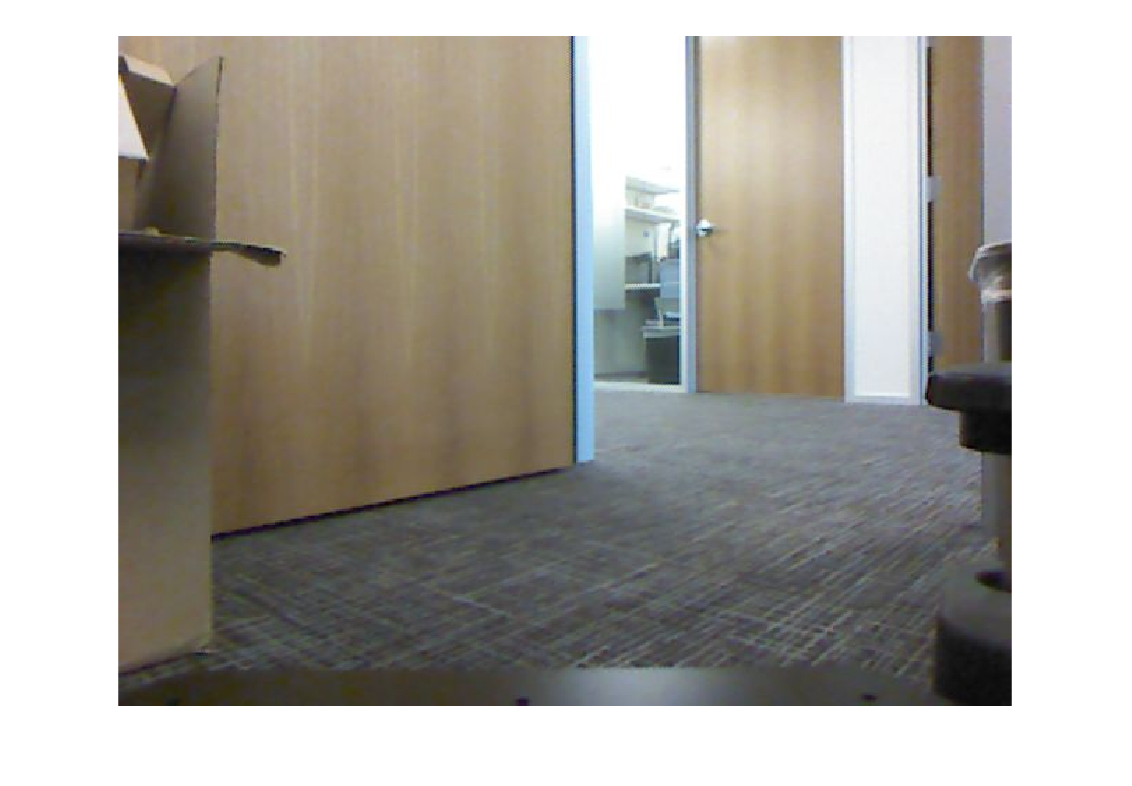

imshow(compressedFormatted)

Most image formats are supported for the compressed image message type. The `16UC1` and `32FC1` encodings are not supported for compressed depth images. Monochromatic and color image encodings are supported.

## Point Cloud Messages

Point clouds can be captured by a variety of sensors used in robotics, including LIDARs, Kinect®, and stereo cameras. The most common message type in ROS for transmitting point clouds is `sensor_msgs/PointCloud2` and MATLAB provides some specialized functions for you to work with this data.

You can see the standard ROS format for a point cloud message by creating an empty point cloud message.

emptyptcloud = rosmessage("sensor_msgs/PointCloud2",DataFormat="struct")

emptyptcloud = struct with fields:
    MessageType: 'sensor_msgs/PointCloud2'
         Header: [1×1 struct]
         Height: 0
          Width: 0
         Fields: [0×1 struct]
    IsBigendian: 0
      PointStep: 0
        RowStep: 0
           Data: [0×1 uint8]
        IsDense: 0


View the populated point cloud message that is stored in the `ptcloud` variable in your workspace:

ptcloud

ptcloud = struct with fields:
    MessageType: 'sensor_msgs/PointCloud2'
         Header: [1×1 struct]
         Height: 480
          Width: 640
         Fields: [4×1 struct]
    IsBigendian: 0
      PointStep: 32
        RowStep: 20480
           Data: [9830400×1 uint8]
        IsDense: 0


### What do these fields mean?

This **point cloud message** is structured as a **ROS (Robot Operating System) message** of type [`sensor_msgs/PointCloud2`.](https://docs.ros.org/en/humble/p/sensor_msgs/msg/PointCloud2.html) Each field in the structure has a specific meaning:

**Breakdown of Fields:**

**MessageType: 'sensor_msgs/PointCloud2'**

- Specifies the ROS message type (`sensor_msgs/PointCloud2`).

- This type is used to represent 3D point cloud data, often from a LiDAR or depth sensor.

**Header: [1x1 struct]**

- The `header` contains metadata about the message, including: 

- **Sequence number (seq):** Tracks message order.

- **Timestamp (stamp):** When the point cloud was captured.

- **Frame ID (frame_id):** Specifies the coordinate frame of reference.

**Height: 480**

- Represents the number of rows in the structured point cloud.

- If **Height = 1**, it means the data is an **unorganized point cloud** (a 1D list of points).

- Here, `480` means the cloud is a **structured** 2D grid.

**Width: 640**

- Represents the number of columns in the structured point cloud.

- Together with `Height`, this implies a **640x480 grid** (e.g., from a depth camera).

**Fields: [4x1 struct]**

- Contains metadata about each point field: x, y, z, and intensity or RGB data.

- Each entry in this structure describes: 

- **    Name: **"x", "y", "z", "intensity"

- **    Offset: **byte location in the data array (see below for more)

- **    Datatype: **float32, uint8, etc.

- **    Count: **number of elements per point

- See tables below for examples of cloud points with only intensity vs color:

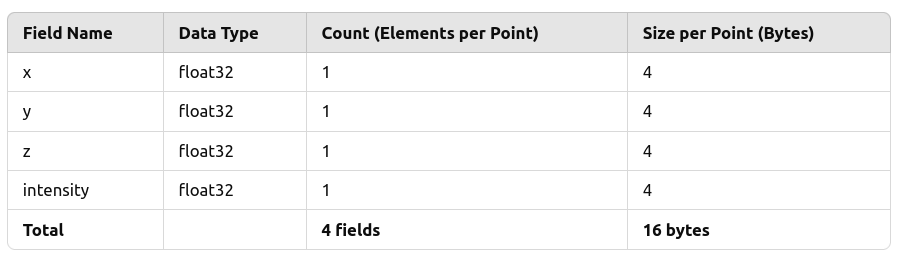

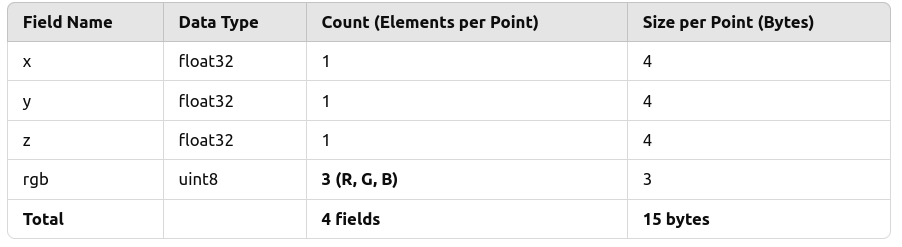

**IsBigendian: 0**

- Indicates byte order.

- **    0** means **little-endian** (least significant byte first).

- **    1** would mean **big-endian**.

**PointStep: 32**

- The number of bytes per cloud point. You might think it is 16 or 15 as shown above, but there can be **padding** or **extra unused fields.**

- This defines how much memory each point in the cloud occupies.

**RowStep: 20480**

- The number of bytes for each **row** in the point cloud.

- Computed as: $RowStep = PointStep \times  Width = 32\times 640=20480\text{RowStep} = \text{PointStep} \times \text{Width} = 32 \times 640 = 20480$

**Data: [9830400x1 uint8]**

- The actual **binary** point cloud data, stored as an **array of bytes** (`uint8`).

- The total number of bytes: $480\times 20480=9830400480 \times 20480 = 9830400$

- The data needs to be parsed based on `Fields`, `PointStep`, and `RowStep`.

**IsDense: 0**

- Indicates whether the cloud has **invalid (NaN/inf) points**.

- **1 (true):** No invalid points, all points are valid.

- **0 (false):** There may be missing or invalid points in the cloud.

**Summary:**

This ROS PointCloud2 message represents a **structured** (480x640) point cloud, likely from a depth sensor, with `x, y, z, intensity` fields. The data is stored in little-endian format, with each point occupying 32 bytes, and the total binary data size is **9,830,400 bytes**.

The method [rosReadAllFieldNames](docid:ros_ref#buqbkiq) function shows these:

fieldNames = rosReadAllFieldNames(ptcloud)

fieldNames = 1×4 cell array
    {'x'}    {'y'}    {'z'}    {'rgb'}


The loaded point cloud message contains four fields `x`, `y`, `z`, and `rgb`.    

### Extract XYZ Data

The point cloud information is encoded in the `Data` property of the message. You can extract the *x*`,`*y*`,`*z* coordinates as an *N*-by-3 matrix by calling the [rosReadXYZ](docid:ros_ref#buqbra8) function. You will get the 640 x 480 array of (x,y,z) points, where each row identifies a point.

xyz = rosReadXYZ(ptcloud)

xyz = 307200×3 single matrix
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN
   NaN   NaN   NaN


`NaN` in the point cloud data indicates that some of the *x*`,`*y*`,`*z* values are not valid. This is an artifact of the Kinect® sensor, and you can safely remove all `NaN` values.

xyzValid = xyz(~isnan(xyz(:,1)),:)

xyzValid = 193359×3 single matrix
    0.1378   -0.6705    1.6260
    0.1409   -0.6705    1.6260
    0.1433   -0.6672    1.6180
    0.1464   -0.6672    1.6180
    0.1502   -0.6705    1.6260
    0.1526   -0.6672    1.6180
    0.1556   -0.6672    1.6180
    0.1587   -0.6672    1.6180
    0.1618   -0.6672    1.6180
    0.1649   -0.6672    1.6180


### Extract RGB Data

Some point cloud sensors also assign RGB color values to each point in a point cloud. If these color values exist, you can retrieve them with a call to [rosReadRGB](docid:ros_ref#buqbpn2).

rgbData = rosReadRGB(ptcloud)

rgbData = 307200×3 single matrix
    0.8392    0.7059    0.5255
    0.8392    0.7059    0.5255
    0.8392    0.7137    0.5333
    0.8392    0.7216    0.5451
    0.8431    0.7137    0.5529
    0.8431    0.7098    0.5569
    0.8471    0.7137    0.5569
    0.8549    0.7098    0.5569
    0.8588    0.7137    0.5529
    0.8627    0.7137    0.5490


### Plot a Static Point Cloud

You can visualize the point cloud with the `rosPlot` function. [rosPlot](docid:ros_ref#buqbjtl) automatically extracts the *x*`,`*y*`,`*z* coordinates and the RGB color values (if they exist) and show them in a 3-D scatter plot. The `rosPlot` function ignores all `NaN` *x*`,`*y*`,`*z* coordinates, even if RGB values exist for that point.

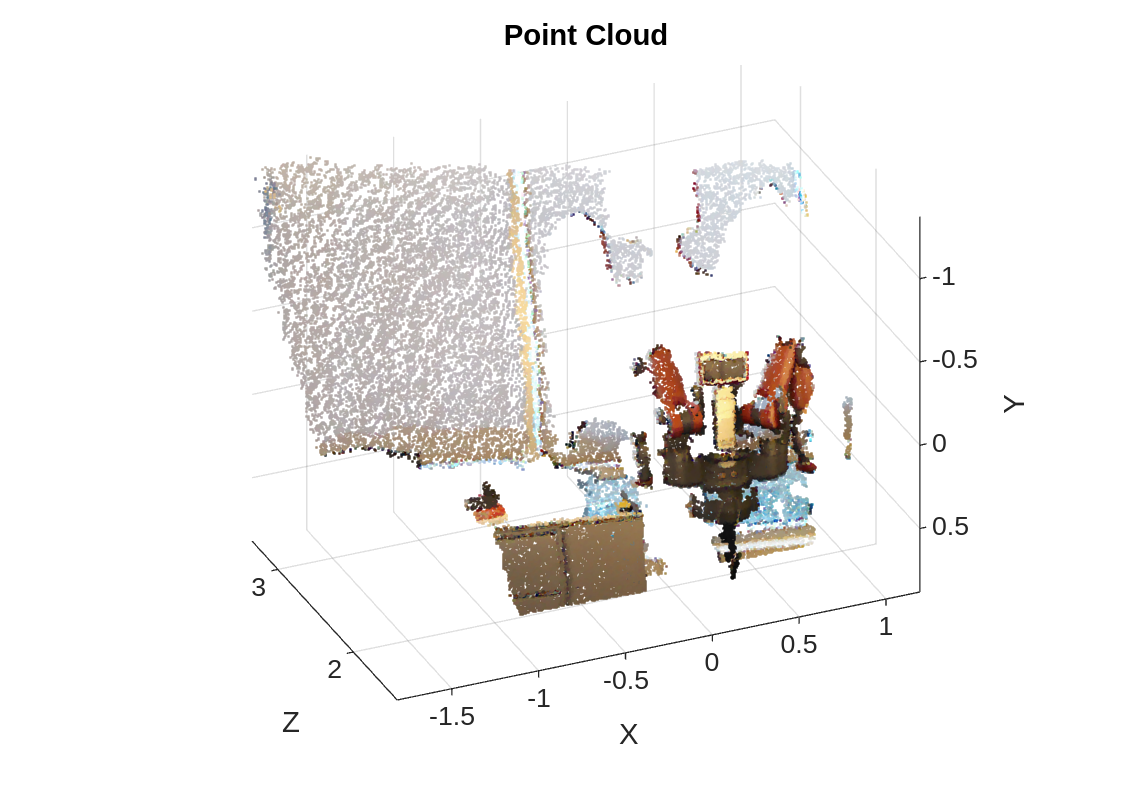

rosPlot(ptcloud)

### Plot Dynamic Point Cloud

MATLAB has a built in function called [pcshow](https://www.mathworks.com/help/releases/R2024b/vision/ref/pcshow.html?searchPort=37101#mw_abe4e51c-5cf0-4b26-9edc-e8b0b4961b02)(), which dynamically displays points using the locations and colors stored in the point cloud object.

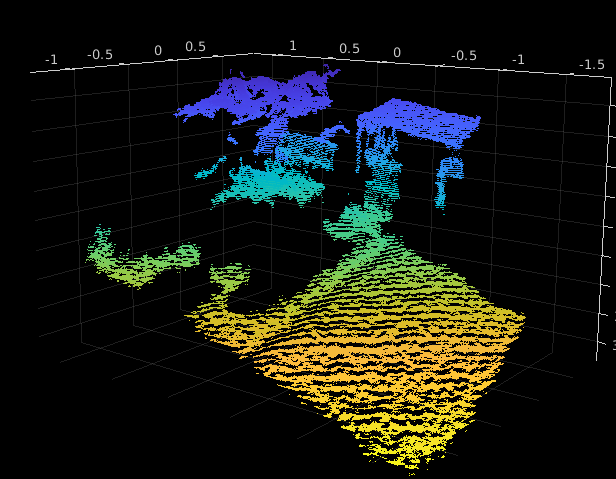

Click on the link for pcshow() to see the full breakdown. 

Given your xyz points (or xyzValid points):

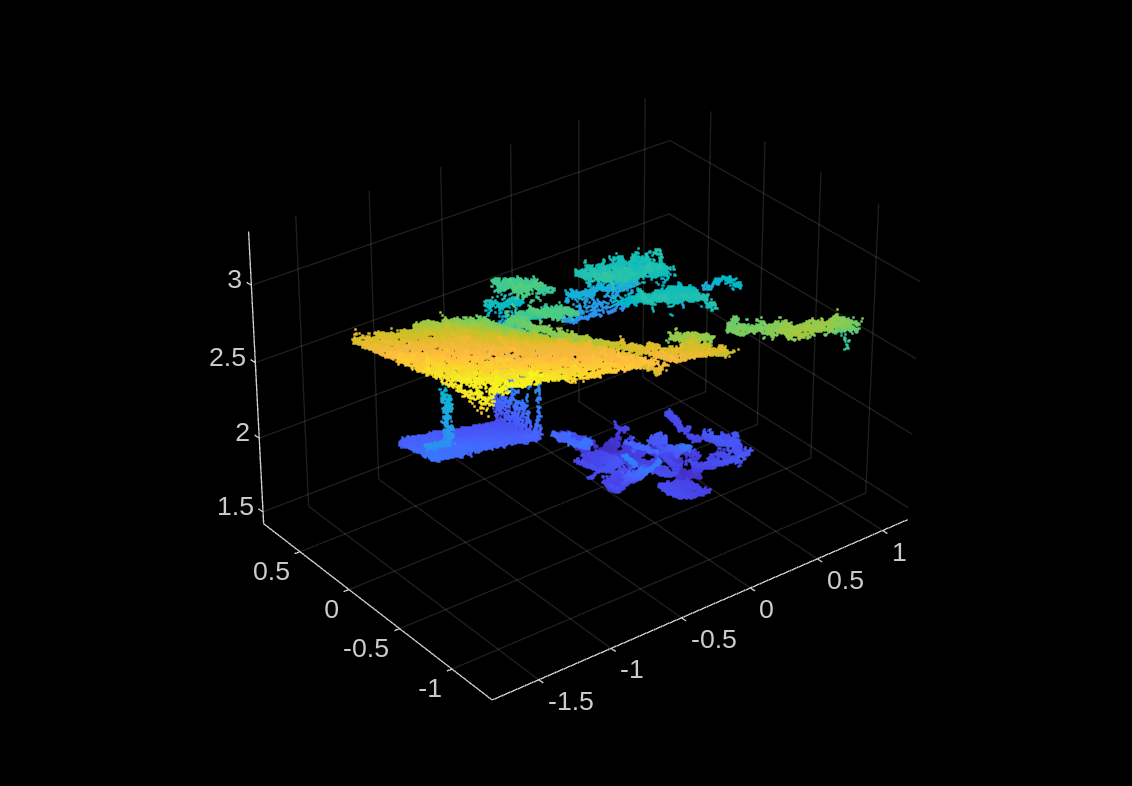

pcshow(xyz);

And with color (we chose xyz since rbgData is currently associated with all indices):

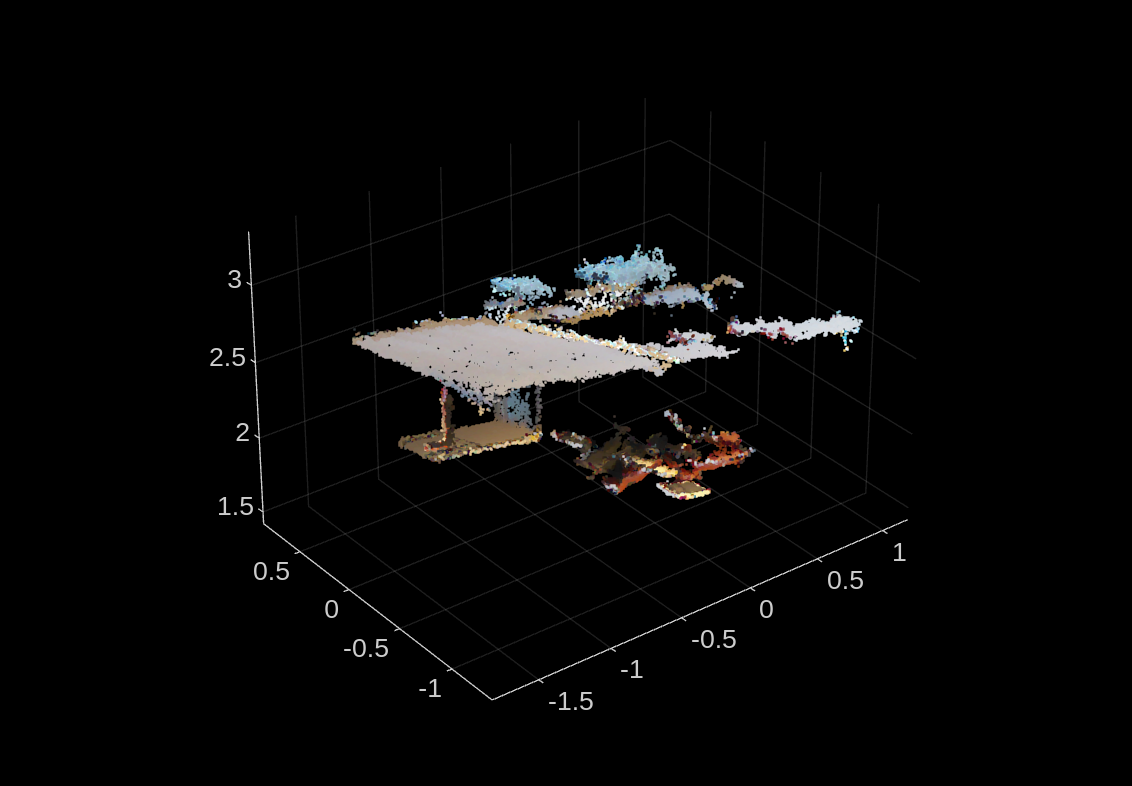

pcshow(xyz,rgbData)

### Display as a Pure Color Images

To access field data use the [rosReadField](docid:ros_ref#buqbota) function. Here is an example of how to access and display a color image from the point cloud:

**Check for RGB Field:**

- The code checks if the point cloud data contains an "rgb" field by looking for that term in `fieldNames`.

- If it does, it proceeds to extract and process this RGB information.

**Read and Convert to Unsigned 8-bit Integer:**

- `rosReadField(ptcloud, "rgb")` reads the "rgb" field from the point cloud.

- `typecast(..., "uint8")` converts the field data into an array of 8-bit unsigned integers. This ensures each color channel is represented as a byte.

**Reshape and Permute the Bytes:**

- First, `reshape(rawData, 4, [])` arranges the stream of bytes into 4 rows. Each group of 4 bytes corresponds to one pixel's RGBA channels.

- Then `permute(..., [3,2,1])` swaps the dimensions so they fit the structure needed for an image representation.

- Finally, `reshape(..., ptcloud.Width, ptcloud.Height, 4)` reshapes that data into a 3D array with dimensions: `[Width, Height, 4]`.

**Extract and Arrange RGB Channels:**

- `pcImg = permute(tmp(:,:,[3,2,1]), [2 1 3])` reorders the color channels to match the usual RGB ordering (since the data might be stored as BGRA or a similar variant).

- The additional `permute` flips the dimensions from `[Width, Height]` to `[Height, Width]` for correct image orientation.

**Display the Image:**

- `imshow(pcImg)` finally displays the constructed RGB image from the point cloud data.

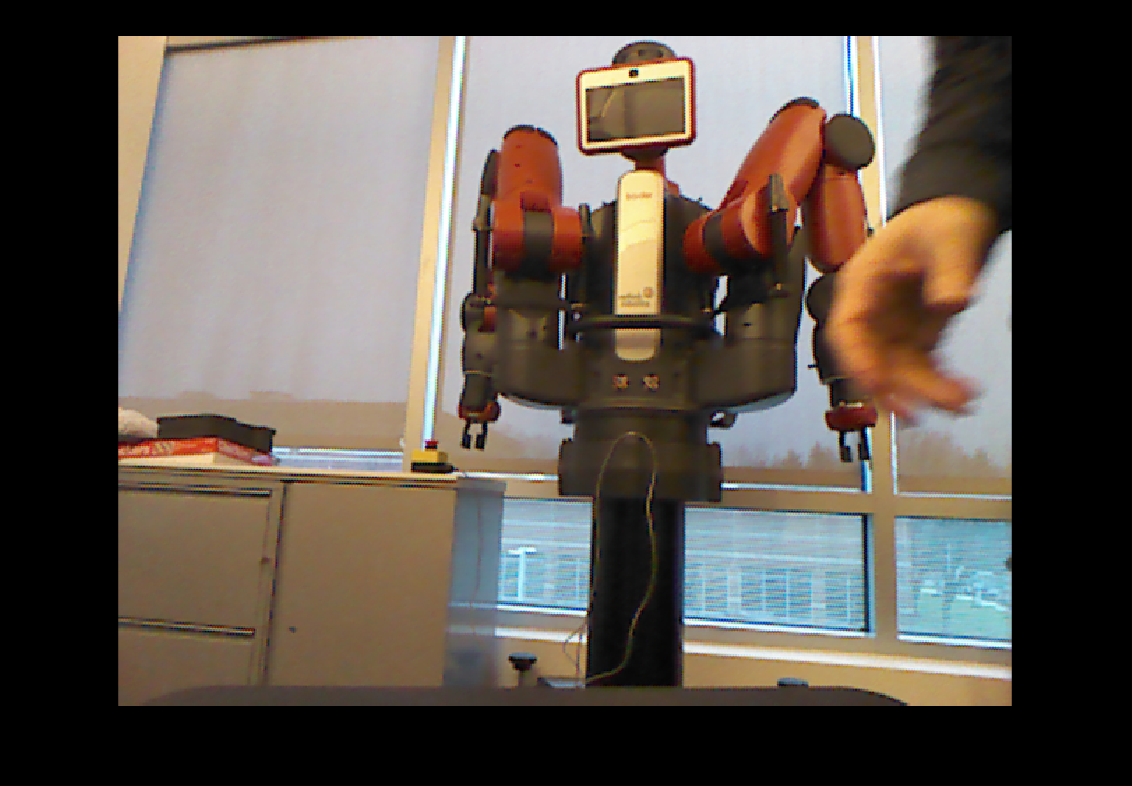

% If it exists, extract the "rgb" field in the point cloud  
if any(contains(fieldNames,"rgb"))

    % Cast to uint8 to have up to 256 values of color intensity (maximum threshold of human sensitivity).
    rawData = typecast(rosReadField(ptcloud,"rgb"),"uint8");

    % 1) Reshape the raw data into groups of 4 bytes (for RGBA)
    % 2) Permute dimensions to suit an image-like structure
    % 3) Reshape to [Width, Height, 4]  
    tmp = reshape( ...
             permute( ...
                 reshape(rawData, 4, []), ...
             [3, 2, 1]), ...
         ptcloud.Width, ptcloud.Height, 4);

    % Reorder channels to get proper RGB arrangement and swap width/height for correct orientation
    pcImg = permute(tmp(:,:,[3,2,1]), [2, 1, 3]);
    
    imshow(pcImg)
    % Display the resulting image
end

Brightness or intensity is the average of all rgb values.

To compute it, know that `rgbData` is:

- an N×3 array (one row per point with [R, G, B] in columns), 

- We need to take the sum over the rows not the columns.

- The function's [sum](https://www.mathworks.com/help/matlab/ref/double.sum.html)[()](https://www.mathworks.com/help/matlab/ref/double.sum.html) 2nd argument can take a '1' for columns or a a '2' for the rows.  

intensity = (1/3) * sum(rgbData,2)

intensity = 307200×1 single column vector
    0.6902
    0.6902
    0.6954
    0.7020
    0.7033
    0.7033
    0.7059
    0.7072
    0.7085
    0.7085


### How to Instantiate a Point Cloud from Scratch

Earlier we created a message of type point cloud, let's bring back that command for convenience:

emptyptcloud = rosmessage("sensor_msgs/PointCloud2",DataFormat="struct")

emptyptcloud = struct with fields:
    MessageType: 'sensor_msgs/PointCloud2'
         Header: [1×1 struct]
         Height: 0
          Width: 0
         Fields: [0×1 struct]
    IsBigendian: 0
      PointStep: 0
        RowStep: 0
           Data: [0×1 uint8]
        IsDense: 0


Let's populate the message with:

- *x, y, z *via [`rosWriteXYZ`](docid:ros_ref#mw_72ca0224-0461-4e53-a12c-61e8d6708666)` using `

- RGB via [`rosWriteRGB`](docid:ros_ref#mw_77a4e46e-0ba7-4a3a-bae0-5dd8484bb51e)

- intensity values [`rosWriteIntensity`](docid:ros_ref#mw_ee1670f0-d729-4143-a185-6de738779197)

We must use a point step size (memory per point) of `32 bytes`.

% x, y, z via rosWriteXYZ using a point step size (memory per point) of 32 bytes.
ptcloudWithIntensity = rosWriteXYZ(emptyptcloud,...
                                   xyz, ...
                                   PointStep=uint32(32));

% RGB via rosWriteRGB
ptcloudWithIntensity = rosWriteRGB(ptcloudWithIntensity, ...
                                    rgbData);

% Intensitiy via rosWriteIntensity
ptcloudWithIntensity = rosWriteIntensity(ptcloudWithIntensity, ...
                                         intensity)

ptcloudWithIntensity = struct with fields:
    MessageType: 'sensor_msgs/PointCloud2'
         Header: [1×1 struct]
         Height: 1
          Width: 307200
         Fields: [5×1 struct]
    IsBigendian: 0
      PointStep: 32
        RowStep: 9830400
           Data: [9830400×1 uint8]
        IsDense: 0


## Quaternion Messages

Quaternions are commonly used in robotics to express orientation. Use [`rosmessage`](docid:ros_ref.bupf5_j_2) to create a quaternion message and observe the fields.

emptyquatmsg = rosmessage("geometry_msgs/Quaternion",DataFormat="struct")

emptyquatmsg = struct with fields:
    MessageType: 'geometry_msgs/Quaternion'
              X: 0
              Y: 0
              Z: 0
              W: 0


For convenience, a quaternion message that represents a 90 degree rotation about the z-axis was loaded from `specialROSMessageData.mat`. Inspect the variable `quatMsg` in your workspace.

quatmsg

quatmsg = struct with fields:
    MessageType: 'geometry_msgs/Quaternion'
              X: 0
              Y: 0
              Z: 0.7071
              W: 0.7071


Create a `quaternion` object from a ROS message using the [rosReadQuaternion](docid:ros_ref#mw_85347c7d-e517-4a81-9e5d-390b49508371) function. The `quaternion` object contains the x, y, z, and w components and provides additional functionalities, such as rotating a point.

quat = rosReadQuaternion(quatmsg)

quat = quaternion
     0.70711 +       0i +       0j + 0.70711k


Define a point in three-dimensional space and rotate it using `rotatepoint` function. Visualize the two points

% Consider some 3D point in space that you will want to rotate.
cartesianPoint = [1,0,1];

% Draw a circle/line (as if to draw a vector) to the original point. 
% Circle
plot3(cartesianPoint(1), ...
      cartesianPoint(2), ...
      cartesianPoint(3),"bo");

hold on; grid on;

% Line
plot3( [0;cartesianPoint(1)], ...
       [0;cartesianPoint(2)], ...
       [0;cartesianPoint(3)],"k")

% Rotate the point by the quaternion
rotationResult = rotatepoint(quat,cartesianPoint);

% Draw a circle/line (as if to draw a vector) to the original point. 
% Circle
plot3(rotationResult(1), ...
      rotationResult(2), ...
      rotationResult(3),"ro")

% Line
plot3( [0;rotationResult(1)], ...
       [0;rotationResult(2)], ...
       [0;rotationResult(3)],"k")

% Axis labels
xlabel("x")
ylabel("y")
zlabel("z")
grid on

## Camera Info Messages

Camera calibration is a commonly used procedure in robotics vision applications. ROS provides `sensor_msgs/CameraInfo` message type to publish calibration information. Use [`rosmessage`](docid:ros_ref.bupf5_j_2) to create a camera info message and observe the fields.

emptycamerainfomsg = rosmessage("sensor_msgs/CameraInfo",DataFormat="struct")

Notably, the message stores the matrices `K` and `P` as vectors. ROS requires these matrices to be stored in row-major format. MATLAB stores matrices in column-major, hence extracting the `K` and `P` matrices requires reshaping and transposing.    

The [`estimateCameraParameters`](docid:vision_ref#btyke8p-1) function can be used to create [`cameraParameters`](docid:vision_ref#mw_16529767-1343-428e-9c2a-3324fcf00d5a) and [`stereoParameters`](docid:vision_ref#bt8mdmz-1) objects. You can create `sensor_msgs/CameraInfo` messages from these objects using the `rosWriteCameraInfo` function. The objects must be converted to structures before use. Load the camera calibration structures.

load("calibrationStructs.mat")

For convenience, the variable `params` loaded from `calibrationStructs.mat` is a fully populated `cameraParameters` struct. Write the `cameraParameters` struct to a new ROS message using the `rosWriteCameraInfo` function.

msg = rosWriteCameraInfo(emptycamerainfomsg,params);

The following table shows the correspondence between the cameraParameters object and the ROS message. 

exampleHelperShowCameraParametersTable

Verify that the intrinsic matrix of the ROS message matches the intrinsic matrix of `params`. 

 K = reshape(msg.K,3,3)'
 intrinsicMatrix = params.IntrinsicMatrix'

For convenience, the variable `stereoParams` loaded from `calibrationStructs.mat` is a fully populated `stereoParameters` struct. Write the `stereoParameters` struct to two new ROS messages using the `rosWriteCameraInfo` function.

[msg1,msg2] = rosWriteCameraInfo(msg,stereoParams);

The following table shows the correspondence between the stereoParameters object and the ROS message. 

exampleHelperShowStereoParametersTable

Verify that the camera 2 rotation matrices of the ROS message and `stereoParams` match.  

R1 = reshape(msg1.R,3,3)';
R2 = reshape(msg2.R,3,3)';
R = R1\R2
rotationOfCamera2 = stereoParams.RotationOfCamera2

Verify that the camera 2 translation vectors of the ROS message and `stereoParams` match.  

P = reshape(msg2.P,4,3)';
P(1:2,end)'
translationOfCamera2 = stereoParams.TranslationOfCamera2(1:2)

## Octomap Messages

ROS uses Octomap messages to implement 3D occupancy grids. Octomap messages are commonly used in robotics applications, such as 3D navigation**. **You can see the standard ROS format for an octomap message by creating an empty message of the appropriate type. 

Use [`rosmessage`](docid:ros_ref.bupf5_j_2) to create the message.

emptyoctomap = rosmessage("octomap_msgs/Octomap",DataFormat="struct")

For convenience, an `octomap` message that is fully populated and is stored in the `octomap` variable loaded from `specialROSMessageData.mat.`

Inspect the variable `octomap` in your workspace. The `Data` field contains the octomap structure in a serialized format.

octomap

Create an [`occupancyMap3D`](docid:nav_ref#mw_3607daa5-c0a8-4e07-9dff-a0b8679e0e6d) object from the ROS message using the [rosReadOccupancyMap3D](docid:ros_ref#mw_936ca20c-8ee3-4bc4-9d42-297c401d96ec) function. Display the 3D occupancy map using the `show` function.

occupancyMap3DObj = rosReadOccupancyMap3D(octomap);
show(occupancyMap3DObj)

## Laser Scan Messages

Laser scanners are commonly used sensors in robotics. ROS provides `sensor_msgs/LaserScan` message type to publish laser scan messages. Use [`rosmessage`](docid:ros_ref.bupf5_j_2) to create a laser scan message and observe the fields.

emptyscan = rosmessage("sensor_msgs/LaserScan","DataFormat","struct")

Since you created an empty message, `emptyscan` does not contain any meaningful data. For convenience, a laser scan message that is fully populated and is stored in the `scan` variable was loaded from `specialROSMessageData.mat`.

Inspect the `scan` variable. The primary data in the message is in the `Ranges` property. The data in `Ranges` is a vector of obstacle distances recorded at small angle increments.

scan

You can get the scan angles from the ROS message using the [rosReadScanAngles](docid:ros_ref#bus65fa-1) function. Visualize the scan data in polar coordinates using the `polarPlot` function.  

angles = rosReadScanAngles(scan);
figure
polarplot(angles,scan.Ranges,LineWidth=2)
title("Laser Scan")

You can get the measured points in Cartesian coordinates using the [rosReadCartesian](docid:ros_ref#buqbmq9) function.

xy = rosReadCartesian(scan);

This populates `xy` with a list of `[x,y]` coordinates that were calculated based on all valid range readings. Visualize the scan message using the [rosPlot](docid:ros_ref#buqbjtl) function:

rosPlot(scan,"MaximumRange",5)

Create a `lidarScan` object from a ROS message using the [rosReadLidarScan](docid:ros_ref#mw_0b6f3410-6381-43f3-bb07-1e0957143a42) function. The `lidarScan` object contains ranges, angles, and Cartesian points and provides additional functionalities, such as transforming the scanned points. Use the `transformScan` function to rotate the scan point and visualize it using `plot`.        

lidarScanObj = rosReadLidarScan(scan)
rotateScan = transformScan(lidarScanObj,[0,0,pi/2]);
plot(rotateScan)

## Occupancy Grid Messages

Occupancy grid messages are commonly used in robotics for 2D navigation applications**. **ROS provides `nav_msgs/OccupancyGrid` message type to publish occupancy grid messages. Use [`rosmessage`](docid:ros_ref.bupf5_j_2) to create an occupancy grid message and observe the fields.

emptyMap = rosmessage("nav_msgs/OccupancyGrid",DataFormat="struct")

Notice that `emptyMap` does not contain any meaningful data. For convenience, an occupancy grid message that is fully populated and is stored in the `mapMsg` variable loaded from `specialROSMessageData.mat.`

Inspect the `mapMsg` variables. The occupancy grid values are encoded in the `Data` field.

mapMsg

Use the [`rosReadOccupancyGrid`](docid:ros_ref#mw_e397bdb0-7aad-4dd5-b6d0-b771237a4841) function to convert the ROS message to an [`occupancyMap`](docid:nav_ref#bvaw60t-1) object. Use the `show` function to display the occupancy grid.

occupancyMapObj = rosReadOccupancyGrid(mapMsg);
show(occupancyMapObj);

You can use the [`occupancyMap`](docid:nav_ref#bvaw60t-1) object functions to manipulate the occupancy grid. Use the `inflate` function to expand the occupied regions. Write the occupancyMap object to a new ROS message using the [rosWriteOccupancyGrid](docid:ros_ref#mw_9d4a4cde-15d2-4810-a7e9-e8f4c078ce9c) function. Use the `show` function to display the new occupancy grid.

inflate(occupancyMapObj,5)
occupancyMapInflatedMsg = rosWriteOccupancyGrid(mapMsg,occupancyMapObj);
show(occupancyMapObj);

Alternatively, you can create a [`binaryOccupancyMap`](docid:nav_ref#bunq527) object from a ROS occupancy grid message using the [`rosReadBinaryOccupancyGrid`](docid:ros_ref#buqblh_) function. A binary occupancy map holds discrete occupancy values of `0` or `1` at each cell whereas an occupancy map holds probability occupancy values that range between `0` and `1` at each cell. Use the `show` function to display the binary occupancy grid.  

binaryMapObj = rosReadBinaryOccupancyGrid(mapMsg);
show(binaryMapObj);

Similarly, you can use the [`binaryOccupancyMap`](docid:nav_ref#bunq527) object functions to manipulate the binary occupancy grid. Use the `inflate` function to alter the binary occupancy grid and create a new ROS message using the [`rosWriteBinaryOccupancyGrid`](docid:ros_ref#buqbl58) function. Use the `show` function to display the new binary occupancy grid. 

inflate(binaryMapObj,5)
binaryMapInflatedMsg = rosWriteBinaryOccupancyGrid(mapMsg,binaryMapObj);
show(binaryMapObj);

*Copyright 2014-2022 The MathWorks, Inc.*